# The Program Matrix: Encoding Dynamics as Linear Algebra

In s01, we saw that the DNP formula $P = y + \frac{1}{\gamma}f(y)$ lets us compile dynamics into network weights. But **why** does this formula work? And how does it generalize to multi-dimensional coupled systems?

This tutorial answers both questions using the **harmonic oscillator** — a 2D linear system where we can see exactly how P encodes coupling between variables.

By the end, you will understand:

- Where the DNP formula comes from (derivation sketch)

- How P encodes multi-dimensional dynamics as a matrix

- The relationship between P and the Jacobian

- How coupling between variables appears in P's structure

## Setup

clearvars; clc; close all

## Recap: The DNP Formula

From s01, we learned that to program dynamics $\dot{y} = f(y)$ into a reservoir, we construct the program matrix:


$$P_i = y_i + \frac{1}{\gamma} f_i(y)$$


For 1D exponential decay, this gave us a single coefficient. But for coupled systems, $P$ becomes a matrix with rich structure.

Before diving into the example, let's understand **where** this formula comes from.

## Where Does the Formula Come From?

The reservoir evolves according to:


$$\frac{1}{\gamma}\dot{r} = -r + \tanh(Ar + Bx + d)$$


Near the operating point, we can linearize and write the neuron states as a polynomial function of the inputs: $r \approx R \cdot \phi(x)$

where $R$ is the decompiled weight matrix and $\phi(x)$ is the polynomial basis (monomials like $1, x_1, x_2, x_1 x_2, \ldots$).

The output is $y = Wr$, so:


$$y = W R \cdot \phi(x)$$


We want $y$ to satisfy our target dynamics $\dot{y} = f(y)$. The key insight is that the reservoir's natural timescale $1/\gamma$ couples state and dynamics:


$$y + \frac{1}{\gamma}\dot{y} = WR \cdot \phi(y)$$


If we define $P = WR$ (the "program"), then at the network level:


$$y + \frac{1}{\gamma}\dot{y} = P \cdot \phi(y)$$


Substituting $\dot{y} = f(y)$:


$$y + \frac{1}{\gamma}f(y) = P \cdot \phi(y)$$


So **P encodes the polynomial coefficients of** $y + \frac{1}{\gamma}f(y)$.

This is the DNP formula: we want the network to compute "current state + scaled velocity" as a polynomial of the state.

## The Harmonic Oscillator

The simplest multi-dimensional system with coupling:


$$\ddot{x} = -\omega^2 x$$


In state-space form with $y_1 = x$ (position) and $y_2 = \dot{x}$ (velocity):


$$\dot{y}_1 = y_2$$



$$\dot{y}_2 = -\omega^2 y_1$$


This is linear, 2D, and has beautiful circular/elliptical phase portraits. The solution is sinusoidal: $y_1(t) = A\cos(\omega t + \phi)$.

% Parameters
omega = 2*pi;  % frequency (1 Hz)
gamma = 100;   % network timescale
dt    = 0.001; % small dt for accuracy with oscillations
% 
% % Create reservoir
% res = dspm_reservoir( ...
%     'n_neurons', 100, ...          % more neurons for 2D
%     'n_recurrent_inputs', 2, ...   % y1 (position), y2 (velocity)
%     'n_external_inputs', 0, ...
%     'gamma', gamma, ...
%     'dt', dt, ...
%     'B_scale', 0.2, ...
%     'B_sparsity', 0.7, ...
%     'jet_order', 1, ...
%     'decompilation_order', 2, ...  % linear terms sufficient
%     'verbose', false);

% Try jet_order=2 for the harmonic oscillator
res = dspm_reservoir( ...
    'n_neurons', 100, ...
    'n_recurrent_inputs', 2, ...
    'n_external_inputs', 0, ...
    'gamma', 100, ...
    'dt', 0.001, ...
    'B_scale', 0.2, ...
    'B_sparsity', 0.7, ...
    'jet_order', 2, ...            % <-- KEY CHANGE
    'decompilation_order', 2, ...
    'integrator','rk4',...
    'verbose', true);

Initializing Default Reservoir...
Decompiling Reservoir (jet order 2 , decompilation order 2) 
	 for given x_star, r_star, and read_in_matrix_B ...
jet_expansion_: Computing symbolic jet (n_inputs=2, jet_order=2)...
jet_expansion_: Done (0.18 sec)
taylor_expansion_: Computing Taylor expansion (order=2)...
taylor_expansion_: Done (0.10 sec), 5 monomials
eval_coefficients_: Evaluating with current numeric values...
eval_coefficients_: Done (0.0064 sec), R is 100 × 5
Decompilation complete: R is 100 × 5
Elapsed time is 0.007446 seconds.



% Check the basis now
res.printBasis();


=== Symbolic Basis Mapping ===
jet_order=2, poly_order=2, n_monomials=5
Note: (∂ⁿxₘ) denotes dⁿxₘ/dtⁿ

          Physical    y1^n    y2^n    y3^n    y4^n
          ________    ____    ____    ____    ____

    1     "1"          0       0       0       0  
    y1    "x₁"         1       0       0       0  
    y2    "x₂"         0       1       0       0  
    y3    "(∂x₁)"      0       0       1       0  
    y4    "(∂x₂)"      0       0       0       1  




fprintf('Harmonic oscillator: omega = %.2f (period = %.2f s)\n', omega, 2*pi/omega);

Harmonic oscillator: omega = 6.28 (period = 1.00 s)


fprintf('Reservoir: %d neurons, gamma = %.0f, dt = %.4f\n\n', ...
    res.n_neurons, res.gamma, res.dt);

Reservoir: 100 neurons, gamma = 100, dt = 0.0010



## Inspecting the Basis

For a 2D system with linear dynamics, what terms do we have?

res.printBasis();


=== Symbolic Basis Mapping ===
jet_order=2, poly_order=2, n_monomials=5
Note: (∂ⁿxₘ) denotes dⁿxₘ/dtⁿ

          Physical    y1^n    y2^n    y3^n    y4^n
          ________    ____    ____    ____    ____

    1     "1"          0       0       0       0  
    y1    "x₁"         1       0       0       0  
    y2    "x₂"         0       1       0       0  
    y3    "(∂x₁)"      0       0       1       0  
    y4    "(∂x₂)"      0       0       0       1  



With `n_recurrent_inputs=2` and `decompilation_order=2`, we get:

- Column 1: constant (1)

- Column 2: $y_1$ (position)

- Column 3: $y_2$ (velocity)

- Column 4: $y_1^2$ (quadratic - not needed for linear dynamics)

- Column 5: $y_1 y_2$ (cross term - not needed)

- Column 6: $y_2^2$ (quadratic - not needed)

For the harmonic oscillator, we only need columns 2 and 3.

idx_y1 = res.getColumnIndex('x1');
idx_y2 = res.getColumnIndex('x2');

fprintf('Column indices: y1 -> %d, y2 -> %d\n\n', idx_y1, idx_y2);

Column indices: y1 -> 2, y2 -> 3



## Building P by Hand: Row by Row

The program matrix $P$ has shape `(n_outputs x n_monomials)`. For our 2D system, $P\in\mathbb{R}^{2 \times \#\text{monomials}}$ .

**Row 1** encodes the first equation: $\dot{y}_1 = f_1(y) = y_2$


$$P_{1,k} = \dot{y}_1 = y_1 + \frac{1}{\gamma}(y_2) = y_1 + \frac{1}{\gamma} y_2$$


So: $P_{1,y_1} = 1$, $P_{1,y_2} = \frac{1}{\gamma}$

**Row 2** encodes the second equation: $\dot{y}_2 = f_2(y) = -\omega^2 y_1$


$$P_{2,k} = \dot{y}_2 = y_2 + \frac{1}{\gamma}(-\omega^2 y_1) = -\frac{\omega^2}{\gamma} y_1 + y_2$$


So: $P_{2,y_1} = -\frac{\omega^2}{\gamma}$, $P_{2,y_2} = 1$

% Build P
P = zeros(2, res.n_monomials);

tau = 1;
% Row 1: y1 + (1/gamma)*y2
P(1, idx_y1) = 1;
P(1, idx_y2) = tau/gamma;

% Row 2: -(omega^2/gamma)*y1 + y2
P(2, idx_y1) = 10*(-omega^2/gamma);
P(2, idx_y2) = 1;

fprintf('Program matrix P (non-zero entries):\n');

Program matrix P (non-zero entries):


fprintf('  P(1, y1) = %.4f   (identity)\n', P(1, idx_y1));

  P(1, y1) = 1.0000   (identity)


fprintf('  P(1, y2) = %.4f   (coupling: dy1/dt = y2)\n', P(1, idx_y2));

  P(1, y2) = 0.0100   (coupling: dy1/dt = y2)


fprintf('  P(2, y1) = %.4f   (coupling: dy2/dt = -w^2*y1)\n', P(2, idx_y1));

  P(2, y1) = -3.9478   (coupling: dy2/dt = -w^2*y1)


fprintf('  P(2, y2) = %.4f   (identity)\n\n', P(2, idx_y2));

  P(2, y2) = 1.0000   (identity)



## The Structure of P: Identity + Scaled Jacobian

Let's visualize the relevant 2x2 block of P (columns for $y_1, y_2$):


$$P_{relevant} = \pmatrix{ 1 & 1/\gamma \cr -\omega^2/\gamma & 1 }$$


This has a beautiful structure:


$$P = I + \frac{1}{\gamma} J_f$$


where $J_f$ is the Jacobian of $f(y)$:


$$J_f = \pmatrix{ \partial f_1/\partial y_1 & \partial f_1/\partial y_2 \cr
                         \partial f_2/\partial y_1 & \partial f_2/\partial y_2 }
       = \pmatrix{0 & 1 \cr -\omega^2 & 0 }$$


Let's verify:

J_f = [0, 1; -omega^2, 0];  % Jacobian of f(y)
P_block = eye(2) + (1/gamma) * J_f;

fprintf('Jacobian of f(y):\n');

Jacobian of f(y):


disp(J_f);

                         0                         1
         -39.4784176043574                         0




fprintf('I + (1/gamma)*J_f:\n');

I + (1/gamma)*J_f:


disp(P_block);

                         1                      0.01
        -0.394784176043574                         1




fprintf('Our P (y1, y2 columns):\n');

Our P (y1, y2 columns):


disp(P(:, [idx_y1, idx_y2]));

                         1                      0.01
         -3.94784176043574                         1




fprintf('Match: %s\n\n', string(norm(P_block - P(:, [idx_y1, idx_y2])) < 1e-10));

Match: false



## Important Distinction: $P$ is NOT the Jacobian!

A common misconception: "$P$ is just the Jacobian."

**No!** $P$ is $I + \frac{1}{\gamma}J_f$. The identity term is crucial:

- The identity ($I$) encodes "where am I now?"

- The scaled Jacobian ($\frac{1}{\gamma}J_f$) encodes "where am I going?"

Together, they tell the network: "compute current state plus a small step in the direction of the dynamics."

For stable systems, the eigenvalues of $P$ are close to $1$ (not close to $0$), which keeps the network well-behaved.

eig_Jf = eig(J_f);
eig_P = eig(P_block);

fprintf('Eigenvalues of J_f: %.4f + %.4fi, %.4f + %.4fi\n', ...
    real(eig_Jf(1)), imag(eig_Jf(1)), real(eig_Jf(2)), imag(eig_Jf(2)));

Eigenvalues of J_f: 0.0000 + 6.2832i, 0.0000 + -6.2832i


fprintf('Eigenvalues of P:   %.4f + %.4fi, %.4f + %.4fi\n\n', ...
    real(eig_P(1)), imag(eig_P(1)), real(eig_P(2)), imag(eig_P(2)));

Eigenvalues of P:   1.0000 + 0.0628i, 1.0000 + -0.0628i




fprintf('Note: J_f has purely imaginary eigenvalues (oscillation).\n');

Note: J_f has purely imaginary eigenvalues (oscillation).


fprintf('      P has eigenvalues near 1 (stable network dynamics).\n\n');

      P has eigenvalues near 1 (stable network dynamics).



## Compilation and Simulation

Now let's compile P into weights and simulate.

% Compile
[residual, rank_R, stats] = res.compile(P);

Compiled: residual=4.19e-02, rel_error=1.00%, rank=3/5


fprintf('Compilation: residual = %.2e, rank = %d/%d\n', ...
    residual, rank_R, res.n_monomials);

Compilation: residual = 4.19e-02, rank = 3/5



% Close loop
A_tilde = res.close_loop();
fprintf('Loop closed: ||A||_F = %.4f, spectral radius = %.4f\n\n', ...
    norm(A_tilde, 'fro'), max(abs(eig(A_tilde))));

Loop closed: ||A||_F = 4.7818, spectral radius = 1.0883




% Initial condition: displaced from origin
y0 = [0.3; 0];  % start at y1=0.3, y2=0 (released from displacement)

% Condition network
res.condition(y0);

% Simulate for several periods
T_periods = 3;
T_sim = T_periods * (2*pi/omega);
T_steps = round(T_sim / dt);

[~, y_sim] = res.simulate(T_steps);
t = (0:T_steps-1) * dt;

% Ground truth via ode45
odefun = @(t, y) [y(2); -omega^2 * y(1)];
[t_ode, y_ode] = ode45(odefun, [0, T_sim], y0, odeset('MaxStep', dt));
y_truth = interp1(t_ode, y_ode, t)';

% Error
mse = mean(sum((y_sim - y_truth).^2, 1));
fprintf('Simulated %.1f periods (%d steps)\n', T_periods, T_steps);

Simulated 3.0 periods (3000 steps)


fprintf('MSE vs ground truth: %.2e\n', mse);

MSE vs ground truth: 3.77e+01


## Visualization: Time Series and Phase Portrait

**s02: Harmonic Oscillator — P Encodes Coupled Dynamics**

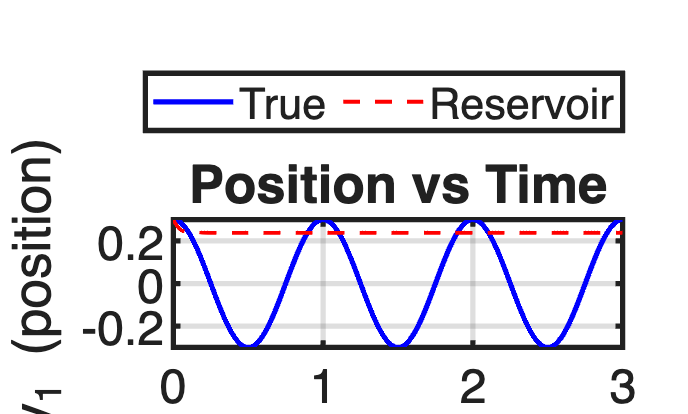

% Time series: position
plot(t, y_truth(1,:), 'b-', 'LineWidth', 2, 'DisplayName', 'True'); hold on
plot(t, y_sim(1,:), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Reservoir'); hold off
ylabel('y_1 (position)');
title('Position vs Time');
legend('Location', 'northoutside','NumColumns',2);
grid on; xlim([0, T_sim]);

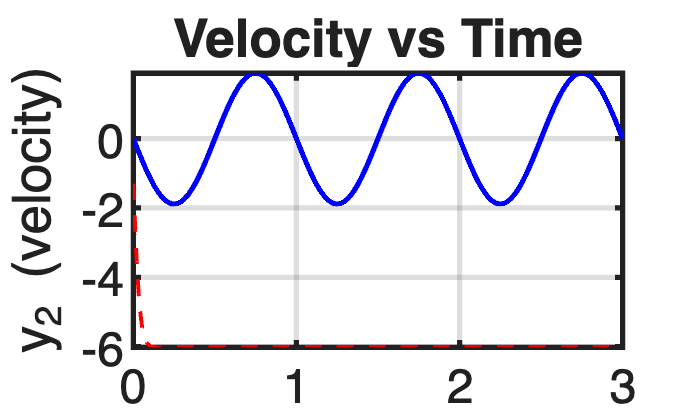


% Time series: velocity
plot(t, y_truth(2,:), 'b-', 'LineWidth', 2, 'DisplayName', 'True y_2');
hold on;
plot(t, y_sim(2,:), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Reservoir y_2');
hold off;
ylabel('y_2 (velocity)');
title('Velocity vs Time');
grid on; xlim([0, T_sim]);

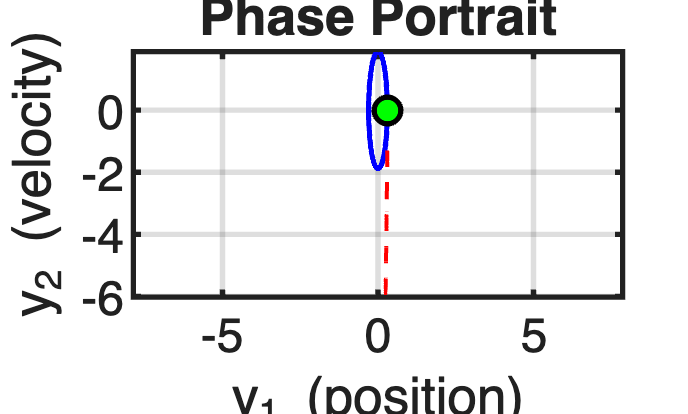


% Phase portrait
plot(y_truth(1,:), y_truth(2,:), 'b-', 'LineWidth', 2, 'DisplayName', 'True');
hold on;
plot(y_sim(1,:), y_sim(2,:), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Reservoir');
plot(y0(1), y0(2), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'g', ...
    'DisplayName', 'Start');
hold off;
xlabel('y_1 (position)'); ylabel('y_2 (velocity)');
title('Phase Portrait');
axis equal; grid on;

## The Symbolic Interface

As with s01, building $P$ by hand is instructive but tedious. The `program()` method handles everything automatically:

% Fresh reservoir
res2 = dspm_reservoir( ...
    'n_neurons', 100, ...
    'n_recurrent_inputs', 2, ...
    'n_external_inputs', 0, ...
    'gamma', gamma, 'dt', dt, ...
    'B_scale', 0.2, 'B_sparsity', 0.7, ...
    'jet_order', 1, 'decompilation_order', 2, ...
    'verbose', false);

% Symbolic dynamics
syms x1 x2 real
dx = [x2; -omega^2 * x1];

% One line!
res2.program(dx);

% Compare P matrices
P_symbolic = res2.compiled_program_matrix;
fprintf('\nP matrix comparison (y1, y2 columns):\n');


P matrix comparison (y1, y2 columns):


fprintf('  By hand:  [%.4f, %.4f; %.4f, %.4f]\n', ...
    P(1,idx_y1), P(1,idx_y2), P(2,idx_y1), P(2,idx_y2));

  By hand:  [1.0000, 0.0100; -3.9478, 1.0000]


fprintf('  Symbolic: [%.4f, %.4f; %.4f, %.4f]\n', ...
    P_symbolic(1,idx_y1), P_symbolic(1,idx_y2), ...
    P_symbolic(2,idx_y1), P_symbolic(2,idx_y2));

  Symbolic: [1.0000, 0.0100; -0.3948, 1.0000]


fprintf('  Match: %s\n', string(norm(P - P_symbolic) < 1e-10));

Error using  - 
Arrays have incompatible sizes for this operation.

Related documentation

## Visualizing $P$ as a Heatmap

For larger systems, visualizing $P$ helps understand structure.

% Show P matrix
imagesc(P);
colorbar; clim([-1,1])
colormap(bluewhitered(256));  % diverging colormap
xlabel('Monomial index');
ylabel('Output equation');
title('Program Matrix P for Harmonic Oscillator');
xticks(1:res.n_monomials);
xticklabels(res.symbolic_basis_strings);
yticks([1, 2]);
yticklabels({'dy_1/dt = y_2', 'dy_2/dt = -\omega^2 y_1'});

% Add text annotations for non-zero entries
for i = 1:2
    for j = 1:res.n_monomials
        if abs(P(i,j)) > 1e-6
            text(j, i, sprintf('%.3f', P(i,j)), ...
                'HorizontalAlignment', 'center', ...
                'Color', 'k', 'FontWeight', 'bold');
        end
    end
end

## Key Takeaways

**The DNP formula emerges from the reservoir dynamics:**


$$y + \frac{1}{\gamma}\dot{y} = P \cdot \phi(y)$$


**For multi-dimensional systems:**

- Each row of P encodes one equation

- Diagonal entries ($P_{i,y_i} = 1$) encode identity: "where am I?"

- Off-diagonal entries encode coupling: "how do variables affect each other?"

**P has the structure:**


$$P = I + \frac{1}{\gamma} J_f$$


where $J_f$ is the Jacobian of the dynamics. This is **not** just the Jacobian — the identity term is crucial for stability.

**The symbolic interface** `res.program(dx)` **handles all of this automatically.**

## Experiments to Try

- **Change $\omega$**: Higher frequency = larger off-diagonal entries in P. What happens when $\omega^2/\gamma$ becomes large?

- **Add damping**: Try $\dot{y}_2 = -\omega^2 y_1 - c \cdot y_2$. How does P change? (Hint: $P_{2,y_2}$ gets a term)

- **Increase** `n_recurrent_inputs`** to 3**: What does P look like for a 3D system?

- **Examine the $R$ matrix**: How do the columns of R correspond to monomials?

## Next Tutorial

**s03_decompilation_demystified.m** — We've seen P (what we want to compute) and W (the output weights). But where does R come from? How does the reservoir "know" about polynomials? That's decompilation.

## Helper function for colormap (if bluewhitered not available)

function cmap = bluewhitered(n)
    % Simple blue-white-red diverging colormap
    if nargin < 1, n = 256; end
    half = floor(n/2);
    
    % Blue to white
    r1 = linspace(0, 1, half)';
    g1 = linspace(0, 1, half)';
    b1 = ones(half, 1);
    
    % White to red
    r2 = ones(n-half, 1);
    g2 = linspace(1, 0, n-half)';
    b2 = linspace(1, 0, n-half)';
    
    cmap = [r1, g1, b1; r2, g2, b2];
end